% This is the testing file for scan conversion

fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Single checkerboard
% B = zeros(h,w);
% B(1:2:h,1:2:w) = ones(ceil(h/2),ceil(w/2));
% B(2:2:h,2:2:w) = ones(floor(h/2),floor(w/2))

% Double checkerboard
% B = zeros(h,w);
% B(1:4:h,1:4:w) = ones(ceil(h/4),ceil(w/4));
% B(1:4:h,2:4:w) = ones(ceil(h/4),floor(w/4));
% B(2:4:h,1:4:w) = ones(floor(h/4),ceil(w/4));
% B(2:4:h,2:4:w) = ones(floor(h/4),floor(w/4));
% 
% B(3:4:h,3:4:w) = ones(ceil(h/4),ceil(w/4)-1);
% B(3:4:h,4:4:w) = ones(ceil(h/4),floor(w/4));
% B(4:4:h,3:4:w) = ones(floor(h/4),ceil(w/4)-1);
% B(4:4:h,4:4:w) = ones(floor(h/4),floor(w/4))


% Make block
a = 1000

a =         1000


b = 2000

b =         2000


c = 6

c =      6


d = 12

d =     12



B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

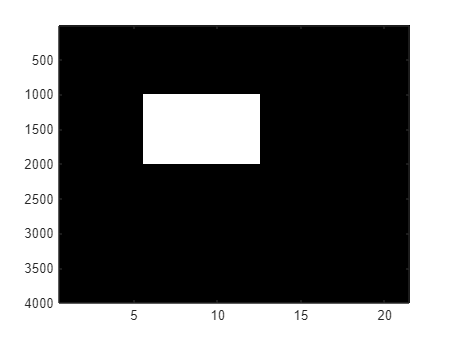


B = B';

figure
colormap(gray)
imagesc(B')


% All ones to view beams
% B = ones(h,w);

imager = 101;
imagec = 201;
ishiftr = floor(imager/2);
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

% Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas; % have spearate lookups for image and for beams??



%precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;


%precompute image rvals
rvals = zeros(imager,imagec);
for rr=1:imager
    for cc=1:imagec
        r = rr-1;
        c = cc - ishiftc - 1;
        rvals(rr,cc) = sqrt(r^2+c^2)/100;
    end
end
rvals;


% for px = 1:imagec
%     for py = 1:imager
%         r = rvals(py,px);
%         n = floor(r*Fs/c);
% 
%         theta = thetas(py,px);
%         k = floor(sin(theta)/2*Fs/fc);
%         kk = k + shift;
%         if (n < h) && (kk < w)
%             blah = B(n,kk);
%         end
%     end
% end
% n
% k
% blah

image = zeros(imager,imagec);


rfpp = (imager-1)/rs(end,1)

rfpp =    4.402509077973718


cfpp = (imagec/2-1)/rs(end,1)

cfpp =    4.380496532583850



aspectRatio = cfpp/rfpp

aspectRatio =    0.995000000000000




%Put things in beams onto image
tic
for kk = 1:w
    k = kk-shift;
    for n = 1:h
        r = rs(n,kk);
        theta = thetas(n,kk);

        y = floor(r*cos(theta)*rfpp);
        x = round(r*sin(theta)*cfpp);

        image(y+1,x+1+ishiftc) = B(kk,n);
    end
end
time = toc

time =    0.009523600000000


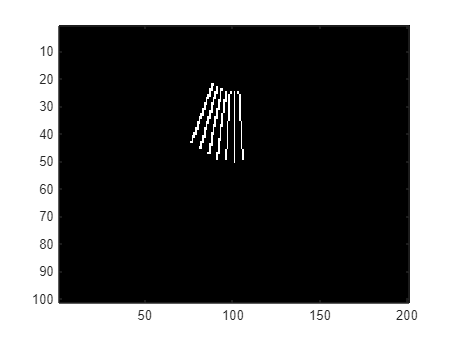

%his time is 0.0466669 but also interpolates



%image = ones(imager,imagec)-image;

figure
colormap(gray)
imagesc(image)


% Now, need to interpolate
image_interp = image;
max_distance = rs(end,1);


tic
for pc = 1:imagec
    for pr = 1:imager
        
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;

        rp = sqrt(px^2+py^2);

        if (rp <= .99*max_distance)
            thetap_test = atan(pc/pr);
            thetap = atan(px/py);

            if (px ~= 0)
                kp = sin(thetap)/2*Fs/fc;
            else
                kp =  0;
            end
        
            np = rp/C*Fs;
            n = floor(np)+1;    
            k = floor(kp);
            kk = k+11;                                               
            if (kp ~= k)
                k1 = k+1;
                
                kk1 = k1+11;
        
                
                n1 = n+1;
        
                r = rs(n,1);
                r1 = rs(n1,1);
                dr = r1-r;
        
                theta = thetas(1,kk);
                theta1 = thetas(1,kk1);
                dtheta = theta1-theta;
        
                beta = (rp - r)/dr;
                alpha = (thetap - theta)/dtheta;
        
                image_interp(pr,pc) = (1-beta)*((1-alpha)*B(kk,n)+alpha*B(kk1,n)) + beta*((1-alpha)*B(kk,n1) + alpha*B(kk1,n1));
            else
                image_interp(pr,pc) = B(kk,n);
            end
        else
            image_interp(pr,pc) = 0;
        end

    end
end
toc

Elapsed time is 0.009197 seconds.


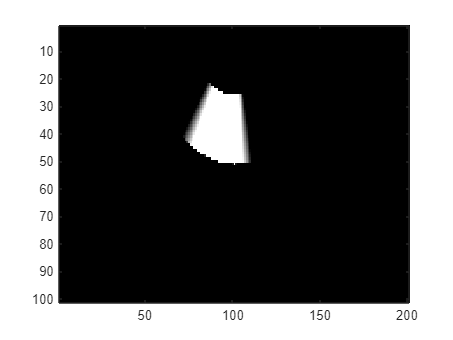


% okay, well already faster


figure
colormap(gray)
imagesc(image_interp)


image_interp;

% compare
B = B*36;

tic
test_image = scan_conversion(B, 21, 4000, 1, 100)

max_pixel =     10


test_image = 1.0e+03 *

   0.010000000000000   0.261811503805468   0.264482911390405   0.267209395198559   0.269992676178910   0.272834547728962   0.275736879552642   0.278701621760425   0.281730809236440   0.284826566297299   0.287991111659750   0.291226763742496   0.294535946331635   0.297921194631548   0.301385161744241   0.304930625603076   0.308560496401558   0.312277824557852   0.316085809262746   0.319987807665893   0.323987344738627   0.328088123899397   0.332294038445441   0.336609183884400   0.341037871229521   0.345584641365123   0.350254280574867   0.355051837343599   0.359982640563045   0.365052319270995   0.370266824085469   0.375632450497105   0.381155864226646   0.386844128837874   0.392704735870029   0.398745637748434   0.404975283778615   0.411402659565145   0.418037330245374   0.424889487977096   0.431970004165800   0.439290487004924   0.446863344965634   0.454701856965723   0.462820250051001   0.471233785549797   0.479958854791475   0.489013085655490   0.49841546141

toc

Elapsed time is 0.035711 seconds.


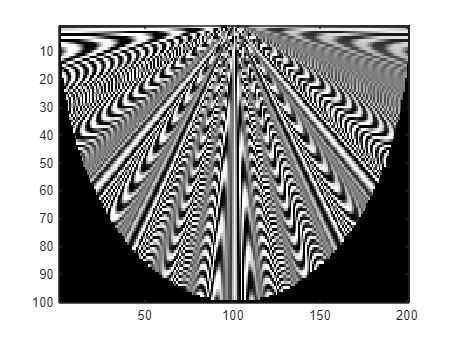


figure
colormap(gray)
imagesc(test_image)

% Figuring out data thing

load sc_image.mat -mat

sc_image

figure
imagesc(sc_image)

% Figuring out data thing

load Mag_image.mat -mat

Mag_image

figure
imagesc(Mag_image)

length(Mag_image)
height(Mag_image)

length(B)
height(B)

% Turning it into a function
fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Make block
a = 1000
b = 2000
c = 6
d = 12

B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B = B';

figure
colormap(gray)
imagesc(B')

imager = 101;
imagec = 201;
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

% Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas; % have spearate lookups for image and for beams??



%precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

rfpp = (imager-1)/rs(end,1)
cfpp = (imagec/2-1)/rs(end,1)

aspectRatio = cfpp/rfpp


max_distance = max(max(rs))


% Run Function and Display
tic
image = scan_conversion1(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance);
toc

figure
colormap(gray)
imagesc(image)




function image_interp = scan_conversion1(Mag_image, beam_index_shift, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance)
    image_interp = zeros(imager,imagec);
    
    for pc = 1:imagec
        for pr = 1:imager
            
            px = (pc-1-ishiftc)/cfpp;
            py = (pr-1)/rfpp;
    
            rp = sqrt(px^2+py^2);
    
            if (rp <= .99*max_distance)
                thetap = atan(px/py);
    
                if (px ~= 0)
                    kp = sin(thetap)/2*Fs/fc;
                else
                    kp =  0;
                end
            
                np = rp/C*Fs;
                n = floor(np)+1;    
                k = floor(kp);
                kk = k+11;                                               
                if (kp ~= k)
                    k1 = k+1;
                    
                    kk1 = k1+beam_index_shift;   
                    n1 = n+1;
            
                    r = rs(n,1);
                    r1 = rs(n1,1);
                    dr = r1-r;
            
                    theta = thetas(1,kk);
                    theta1 = thetas(1,kk1);
                    dtheta = theta1-theta;
            
                    beta = (rp - r)/dr;
                    alpha = (thetap - theta)/dtheta;
            
                    image_interp(pr,pc) = (1-beta)*((1-alpha)*Mag_image(kk,n)+alpha*Mag_image(kk1,n)) + beta*((1-alpha)*Mag_image(kk,n1) + alpha*Mag_image(kk1,n1));
                else
                    image_interp(pr,pc) = Mag_image(kk,n);
                end
            else
                image_interp(pr,pc) = 0;
            end
    
        end
    end
end

% Turning it into a FAST function
fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Make block
a = 1000
b = 2000
c = 6
d = 12

B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B = B';

figure
colormap(gray)
imagesc(B')

imager = 100;
imagec = 201;
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

rfpp = (imager-1)/rs(end,1)
cfpp = (imagec/2-1)/rs(end,1)

max_distance = max(max(rs))

% ============================= %

% ##### - Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precomute px, py, rp, thetap
Pxy = zeros(imager, imagec, 2);
Rpvals = zeros(imager, imagec);
Thetapvals = zeros(imager, imagec);
Kpvals = zeros(imager, imagec);
KNvals = zeros(imager,imagec,2);

Alphas = zeros(imager,imagec);
Betas = zeros(imager,imagec);

for pc = 1:imagec
    for pr = 1:imager
        % Establish x and y
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;        
        Pxy(pr,pc,1) = px;
        Pxy(pr,pc,2) = py;

        % Establish rp and thetap
        rp = sqrt(px^2+py^2);
        Rpvals(pr,pc) = rp;

        thetap = atan(px/py);
        Thetapvals(pr,pc) = thetap;

        % Next, kp, kk, and n
        if (px ~= 0)
            kp = sin(thetap)/2*Fs/fc;
        else
            kp =  0;
        end
        Kpvals(pr,pc) = kp;
          
        k = floor(kp);
        kk = k+shift;
        n = floor(np)+1;  

        KKNvals(pr,pc,1) = kk;
        KKNvals(pr,pc,2) = n;

        % Then, calculate alphas and betas 
        % TODO need to split into alpha and beta seperately
        if (kp==k)
            alpha = 0;
            beta = 0;
        else
            r = rs(n,1);
            r1 = rs(n+1,1);
            dr = r1-r;
    
            theta = thetas(1,kk);
            theta1 = thetas(1,kk+1);
            dtheta = theta1-theta;
            
            alpha = (thetap - theta)/dtheta;
            beta = (rp - r)/dr;  
        end

        Alphas(pr,pc) = alpha;
        Betas(pr,pc) = beta;




    end
end
Pxy(:,:,2);

Alphas;
Betas;


% now, make complex data structure according to image... want all four beam
% values, alpha, and beta
% wait... but don't have it, so have to figure out how to do the math
% let's skip all the edges....
% No, its on beams :(
image = zeros(imager,imagec);
%image(2:imager-1,2:imagec-1) = (1-Betas).*((1-Alphas).*Mag_image(1:image,n)+alpha*Mag_image(kk1,n)) + beta*((1-alpha)*Mag_image(kk,n1) + alpha*Mag_image(kk1,n1))





% =================================== %
% Run Function and Display
aspectRatio = cfpp/rfpp


figure
colormap(gray)
imagesc(image)


% tic
% image = scan_conversion_fast(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance, Pxy);
% toc

function image_interp = scan_conversion_fast(Mag_image, beam_index_shift, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance, Pxy)
    image_interp = zeros(imager,imagec);
    
    for pc = 1:imagec
        for pr = 1:imager
            
            px = Pxy(pr,pc,1);
            py = Pxy(pr,pc,2);
    
            rp = sqrt(px^2+py^2);
    
            if (rp <= .99*max_distance)
                thetap = atan(px/py);
    
                if (px ~= 0)
                    kp = sin(thetap)/2*Fs/fc;
                else
                    kp =  0;
                end
            
                np = rp/C*Fs;
                n = floor(np)+1;    
                k = floor(kp);
                kk = k+11;                                               
                if (kp ~= k)
                    k1 = k+1;
                    
                    kk1 = k1+beam_index_shift;   
                    n1 = n+1;
            
                    r = rs(n,1);
                    r1 = rs(n1,1);
                    dr = r1-r;
            
                    theta = thetas(1,kk);
                    theta1 = thetas(1,kk1);
                    dtheta = theta1-theta;
            
                    beta = (rp - r)/dr;
                    alpha = (thetap - theta)/dtheta;
            
                    image_interp(pr,pc) = (1-beta)*((1-alpha)*Mag_image(kk,n)+alpha*Mag_image(kk1,n)) + beta*((1-alpha)*Mag_image(kk,n1) + alpha*Mag_image(kk1,n1));
                else
                    image_interp(pr,pc) = Mag_image(kk,n);
                end
            else
                image_interp(pr,pc) = 0;
            end
    
        end
    end
end

% Better making it vector
fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Make block
a = 1000
b = 2000
c = 6
d = 12

B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B = B';

figure
colormap(gray)
imagesc(B')

imager = 100;
imagec = 201;
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

rfpp = (imager-1)/rs(end,1)
cfpp = (imagec/2-1)/rs(end,1)

max_distance = max(max(rs))

% ============================= %



% Single checkerboard
% B = zeros(h,w);
% B(1:2:h,1:2:w) = ones(ceil(h/2),ceil(w/2));
% B(2:2:h,2:2:w) = ones(floor(h/2),floor(w/2))

% Double checkerboard
B = zeros(h,w);
B(1:4:h,1:4:w) = ones(ceil(h/4),ceil(w/4));
B(1:4:h,2:4:w) = ones(ceil(h/4),floor(w/4));
B(2:4:h,1:4:w) = ones(floor(h/4),ceil(w/4));
B(2:4:h,2:4:w) = ones(floor(h/4),floor(w/4));

B(3:4:h,3:4:w) = ones(ceil(h/4),ceil(w/4)-1);
B(3:4:h,4:4:w) = ones(ceil(h/4),floor(w/4));
B(4:4:h,3:4:w) = ones(floor(h/4),ceil(w/4)-1);
B(4:4:h,4:4:w) = ones(floor(h/4),floor(w/4))


% Make block
% a = 1000
% b = 2000
% c = 6
% d = 12
% 
% B = zeros(h,w);
% B(a:b,c:d) = ones(b-a+1,d-c+1)

B = B';

figure
colormap(gray)
imagesc(B')

% create 
image = zeros(imager,imagec);
%image(2:end-1,2:end-1);
%B(KKNvals(1:end-2,1:end-2,1));

% ============================= %

% ##### - Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precomute px, py, rp, thetap
Pxy = zeros(imager, imagec, 2);
Rpvals = zeros(imager, imagec);
Thetapvals = zeros(imager, imagec);
Kpvals = zeros(imager, imagec);
KKNvals = zeros(imager,imagec,2);
KK1N1vals = zeros(imager,imagec,2);

Alphas = zeros(imager,imagec);
Betas = zeros(imager,imagec);

for pc = 1:imagec
    for pr = 1:imager
        % Establish x and y
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;        
        Pxy(pr,pc,1) = px;
        Pxy(pr,pc,2) = py;

        % Establish rp and thetap
        rp = sqrt(px^2+py^2);
        Rpvals(pr,pc) = rp;

        thetap = atan(px/py);
        Thetapvals(pr,pc) = thetap;

        % Next, kp, kk, and n
        if (px ~= 0)
            kp = sin(thetap)/2*Fs/fc;
        else
            kp =  0;
        end
        Kpvals(pr,pc) = kp;
          
        k = floor(kp);
        kk = k+shift;

        np = rp/C*Fs;
        n = floor(np)+1;  

        if (n >= length(B))
            n = length(B)-1;
        end

        KKNvals(pr,pc,1) = kk;
        KKNvals(pr,pc,2) = n;

        if (kk >= 21)
            KK1N1vals(pr,pc,1) = kk;
        else
            KK1N1vals(pr,pc,1) = kk+1;
        end

        if (n >= 4000)
            KK1N1vals(pr,pc,2) = n;
        else
            KK1N1vals(pr,pc,2) = n+1;
        end


        % Then, calculate alphas and betas 
        % TODO need to split into alpha and beta seperately
        if (kp==k)
            alpha = 0;
            beta = 0;
        else
            r = rs(n,1);
            r1 = rs(n+1,1);
            dr = r1-r;
    
            theta = thetas(1,kk);
            theta1 = thetas(1,kk+1);
            dtheta = theta1-theta;
            
            alpha = (thetap - theta)/dtheta;
            beta = (rp - r)/dr;  
        end

        Alphas(pr,pc) = alpha;
        Betas(pr,pc) = beta;




    end
end
Pxy(:,:,2);

Alphas;
Betas;





KKNvals(1,100,1),KKNvals(1,100,2)
sub2ind([22 4000],KKNvals(1,100,1),KKNvals(1,100,2))
B(881)
KKNvals(:,:,1)
KKNvals(:,:,2)
sub2ind([22 4000],KKNvals(:,:,1),KKNvals(:,:,2))


% B_temp = [B_temp zeros(22, 1)]

% B_temp = B;


ind_bkn = sub2ind([22 4001],KKNvals(:,:,1),KKNvals(:,:,2));
ind_bk1n = sub2ind([22 4000],KKNvals(:,:,1)+1,KKNvals(:,:,2));
ind_bkn1 = sub2ind([22 4000],KKNvals(:,:,1),KKNvals(:,:,2)+1);
ind_bk1n1 = sub2ind([22 4000],KKNvals(:,:,1)+1,KKNvals(:,:,2)+1);
Bkn = B_temp(ind_bkn)
Bk1n = B_temp(ind_bk1n)
Bkn1 = B_temp(ind_bkn1)
Bk1n1 = B_temp(ind_bk1n1)

BMAM = (1-Betas).*(1-Alphas);
BMA = (1-Betas).*Alphas;
BAM = Betas.*(1-Alphas);
BA = Betas.*Alphas;

%image = Betas

tic
B_temp = [B; zeros(1,4000)];
image=BMAM.*B_temp(ind_bkn)+BMA.*B_temp(ind_bk1n) + BAM.*B_temp(ind_bkn1) + BA.*B_temp(ind_bk1n1);
toc


figure
colormap(gray)
imagesc(image)
title("Test Version")

% Run Function and Display
tic
image = scan_conversion1(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance);
toc

figure
colormap(gray)
imagesc(image)
title("Good Version")

v = magic(5)
v(sub2ind([5 5],[1 1; 3 3],[2 4; 2 4]))

B(sub2ind([21 4000],KKNvals(1:end-2,1:end-2,1),KKNvals(1:end-2,1:end-2,2)))

% Final Function Version
fc = 10000;

% Constant Values
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

imager = 101;
imagec = 201;
ishiftr = floor(imager/2);
ishiftc = floor(imagec/2);


% ============================= %

% Single checkerboard
% B = zeros(h,w);
% B(1:2:h,1:2:w) = ones(ceil(h/2),ceil(w/2));
% B(2:2:h,2:2:w) = ones(floor(h/2),floor(w/2))

% Double checkerboard
B = zeros(h,w);
B(1:4:h,1:4:w) = ones(ceil(h/4),ceil(w/4));
B(1:4:h,2:4:w) = ones(ceil(h/4),floor(w/4));
B(2:4:h,1:4:w) = ones(floor(h/4),ceil(w/4));
B(2:4:h,2:4:w) = ones(floor(h/4),floor(w/4));

B(3:4:h,3:4:w) = ones(ceil(h/4),ceil(w/4)-1);
B(3:4:h,4:4:w) = ones(ceil(h/4),floor(w/4));
B(4:4:h,3:4:w) = ones(floor(h/4),ceil(w/4)-1);
B(4:4:h,4:4:w) = ones(floor(h/4),floor(w/4))

B =      1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     

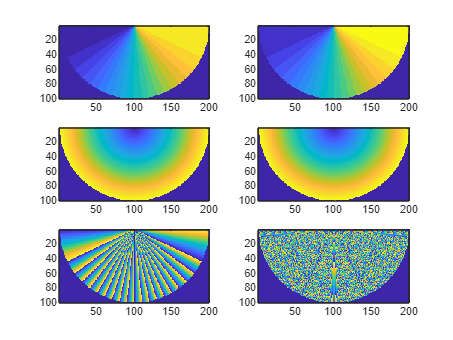


% Block
% a = 1000
% b = 2000
% c = 6
% d = 12
% 
% B = zeros(h,w);
% B(a:b,c:d) = ones(b-a+1,d-c+1)

B = B';

% figure
% colormap(gray)
% imagesc(B')

% ============================= %

% Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas;

% Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% Precompute max distance and ratios
max_distance = 4000*C/Fs;

rfpp = (imager-1)/rs(end,1);
cfpp = (imagec/2-1)/rs(end,1);

% Precomute indexes and alphas/betas
KKNvals = zeros(imager,imagec,2);
KK1N1vals = zeros(imager,imagec,2);
Alphas = zeros(imager,imagec);
Betas = zeros(imager,imagec);

for pc = 1:imagec
    for pr = 1:imager

        % Establish x and y
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;        

        % Establish rp and thetap
        rp = sqrt(px^2+py^2);
        thetap = atan(px/py);

        % Find indexes (kk and n)
        if (px ~= 0) % handle edge case
            kp = sin(thetap)/2*Fs/fc;
        else
            kp =  0;
        end
          
        k = floor(kp);
        kk = k+shift;

        np = rp/C*Fs;
        n = floor(np)+1;  

        if (kk < 21) % bound kk
            KKNvals(pr,pc,1) = kk;
            KK1N1vals(pr,pc,1) = kk+1;
        elseif (kk==21)
            KKNvals(pr,pc,1) = 21;
            KK1N1vals(pr,pc,1) = 21;
        else
            KKNvals(pr,pc,1) = 1;
            KKNvals(pr,pc,2) = 1;
            KK1N1vals(pr,pc,2) = 1;
            KK1N1vals(pr,pc,2) = 1;
        end

        if (n < 4000) % bound n
            KKNvals(pr,pc,2) = n;
            KK1N1vals(pr,pc,2) = n+1;
        elseif (n==4000)
            KKNvals(pr,pc,2) = 4000;
            KK1N1vals(pr,pc,2) = 4000;
        else
            KKNvals(pr,pc,1) = 1;
            KKNvals(pr,pc,2) = 1;
            KK1N1vals(pr,pc,1) = 1;
            KK1N1vals(pr,pc,2) = 1;
        end

        % Then, calculate alphas and betas 
        if (n>=4000)||(kk>=21)||(kp==k)||(np==n)
            alpha = 0;
            beta = 0;
        else
            r = rs(n,1);
            r1 = rs(n+1,1);
            dr = r1-r;
    
            theta = thetas(1,kk);
            theta1 = thetas(1,kk+1);
            dtheta = theta1-theta;
            
            alpha = (thetap - theta)/dtheta;
            beta = (rp - r)/dr;  
        end

        Alphas(pr,pc) = alpha;
        Betas(pr,pc) = beta;

    end
end

figure
subplot(3,2,1)
imagesc(KKNvals(:,:,1))
subplot(3,2,2)
imagesc(KK1N1vals(:,:,1))
subplot(3,2,3)
imagesc(KKNvals(:,:,2))
subplot(3,2,4)
imagesc(KK1N1vals(:,:,2))
subplot(3,2,5)
imagesc(Alphas)
subplot(3,2,6)
imagesc(Betas)


% Precompute linear indexes
ind_bkn = sub2ind([21 4000],KKNvals(:,:,1),KKNvals(:,:,2));
ind_bk1n = sub2ind([21 4000],KK1N1vals(:,:,1),KKNvals(:,:,2));
ind_bkn1 = sub2ind([21 4000],KKNvals(:,:,1),KK1N1vals(:,:,2));
ind_bk1n1 = sub2ind([21 4000],KK1N1vals(:,:,1),KK1N1vals(:,:,2));


% Precompute Scaling Factors (Beta/Alpha, Minus)
BMAM = (1-Betas).*(1-Alphas);
BMA = (1-Betas).*Alphas;
BAM = Betas.*(1-Alphas);
BA = Betas.*Alphas;


% Define function

function image = scan_conversion_v(B,ind_bkn,ind_bk1n, ind_bkn1, ind_bk1n1, BMAM, BMA, BAM, BA)
    image=BMAM.*B(ind_bkn)+BMA.*B(ind_bk1n) + BAM.*B(ind_bkn1) + BA.*B(ind_bk1n1);
end


% Vector function
sum = 0;
N = 100;
for i=1:N
    tic
    scan_conversion_v(B,ind_bkn,ind_bk1n, ind_bkn1, ind_bk1n1, BMAM, BMA, BAM, BA);
    sum = sum+toc;
end
avg_time_vector = sum/N;

% Loop Function
sum = 0;
for i=1:N
    tic
    scan_conversion1(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance);
    sum = sum+toc;
end
avg_time_loop = sum/N;

% Provided Function
B = B*36;
sum = 0;
for i=1:N
    tic
    scan_conversion(B, 21, 4000, 1, 100);
    sum = sum+toc;
end

max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


max_pixel =     10


avg_time_provided = sum/N;


% Results

timing = [avg_time_vector; avg_time_loop; avg_time_provided]

timing =    0.000540881000000
   0.002006525000000
   0.002628047000000


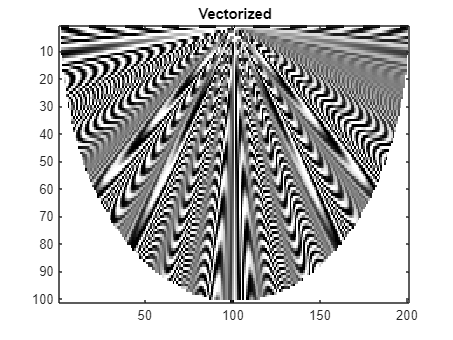


image = scan_conversion_v(B,ind_bkn,ind_bk1n, ind_bkn1, ind_bk1n1, BMAM, BMA, BAM, BA);
figure
colormap(gray)
imagesc(image)
title("Vectorized")

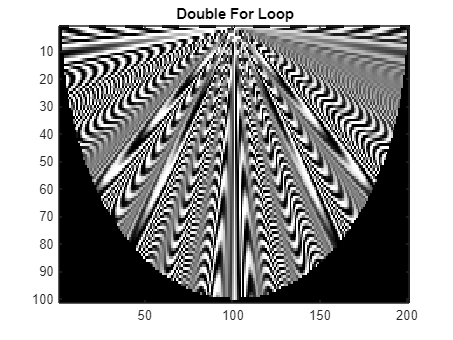


test_image=scan_conversion1(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance);
figure
colormap(gray)
imagesc(test_image)
title("Double For Loop")


test_image = scan_conversion(B, 21, 4000, 1, 100);

max_pixel =     10


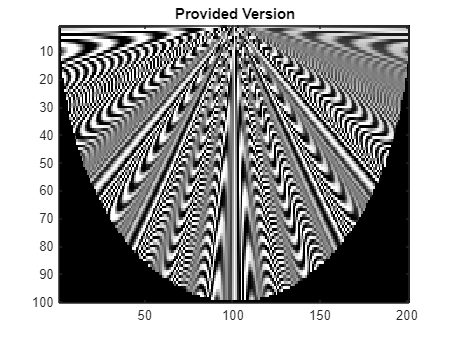

figure
colormap(gray)
imagesc(test_image)
title("Provided Version")

% ============================= %

% Block
a = 1000
b = 1100
c = 1
d = 1

B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)
B = B';

figure
colormap(gray)
imagesc(B')


% Block2
a = 3900
b = 4000
c = 11
d = 11

B2 = zeros(h,w);
B2(a:b,c:d) = ones(b-a+1,d-c+1)
B2 = B2';

figure
colormap(gray)
imagesc(B2')

% ============================= %

image = scan_conversion_v(B,ind_bkn,ind_bk1n, ind_bkn1, ind_bk1n1, BMAM, BMA, BAM, BA);
figure
colormap(gray)
imagesc(image)
title("Test Image 1")

image2 = scan_conversion_v(B2,ind_bkn,ind_bk1n, ind_bkn1, ind_bk1n1, BMAM, BMA, BAM, BA);
figure
colormap(gray)
imagesc(image2)
title("Test Image 2")

save("nicksImages.mat","image","image2")

h = 4000
w = 21
fc = 10000
Fs = 200000

thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas